%% =========================================================
%  MULTI-GROUP SCOUT RESULTS VS LESION
%
%  INPUTS:
%   - cortex exported from Brainstorm
%   - lesion scout exported separately (mask)
%   - group scouts exported separately:
%       spike, spikeHFO, HFO
%
%  OUTPUT:
%   - ResultsTable with:
%       * NumVertices
%       * ScoutArea_cm2
%       * DistanceMaxPoints_mm
%       * MeanDistance_mm
%       * MedianDistance_mm
%       * SpatialDispersion_RMS_mm
%       * StdDistance_mm
%   - Raincloud plots:
%       * distance to lesion (one subplot per group)
%       * spatial dispersion (one subplot per group)
%   - Vertex-wise distances with violin + scatter
%   - 3D reconstruction per group
%   - HTML report with table + figures
%% =========================================================

clear; clc; close all;

%% =========================
% 1) FILES: EDIT THESE PATHS
%% =========================

cortex_file    = 'C:\Users\prego\Documents\brainstorm_db\ESI_10-10_12-03-2026_AA\anat\AA\tess_cortex_pial_low.mat';

mask_file      = 'C:\Users\prego\Documents\datos_brainstorm\pacientes_rafa\AA\scout_lesion_mask.mat';
spike_file     = 'C:\Users\prego\Documents\datos_brainstorm\pacientes_rafa\AA\scout_lesion_spike.mat';
spikeHFO_file  = 'C:\Users\prego\Documents\datos_brainstorm\pacientes_rafa\AA\scout_lesion_spikeHFO.mat';
HFO_file       = 'C:\Users\prego\Documents\datos_brainstorm\pacientes_rafa\AA\scout_lesion_HFO.mat';

% Brainstorm usually stores vertices in meters
% Multiply by 1000 to work in mm
unit_scale = 1000;

% Bootstrap samples for dispersion raincloud
nBoot = 1000;

%% =========================
% 2) LOAD DATA
%% =========================

sCortex  = load(cortex_file);
mask     = load(mask_file);
spike    = load(spike_file);
spikeHFO = load(spikeHFO_file);
HFO      = load(HFO_file);

% --- Cortex vertices ---
if isfield(sCortex, 'Vertices')
    VerticesRaw = sCortex.Vertices;
elseif isfield(sCortex, 'sSurf') && isfield(sCortex.sSurf, 'Vertices')
    VerticesRaw = sCortex.sSurf.Vertices;
else
    error('No se ha encontrado el campo Vertices en el archivo del cortex.');
end

% --- Cortex faces ---
Faces = [];
if isfield(sCortex, 'Faces')
    Faces = sCortex.Faces;
elseif isfield(sCortex, 'sSurf') && isfield(sCortex.sSurf, 'Faces')
    Faces = sCortex.sSurf.Faces;
else
    warning('No se ha encontrado Faces. El cálculo del área del scout no funcionará.');
end

% Coordinates in mm
VerticesMM = VerticesRaw * unit_scale;

%% =========================
% 3) EXTRACT LESION SCOUT
%% =========================

maskScout = get_first_scout(mask, 'mask');
lesion_vertices = maskScout.Vertices;
lesion_seed     = get_scout_seed(maskScout);

if isempty(lesion_vertices)
    error('El scout de lesión no contiene vértices.');
end

lesion_coords_mm = VerticesMM(lesion_vertices, :);
lesion_seed_mm   = VerticesMM(lesion_seed, :);

%% =========================
% 4) DEFINE GROUPS
%% =========================

group_names  = {'Spike', 'Spike+HFO', 'HFO'};
group_files  = {spike, spikeHFO, HFO};

% Same color palette as before
group_colors = [
    0.20 0.45 0.85   % blue
    0.85 0.40 0.20   % orange/red
    0.25 0.65 0.35   % green
];

nGroups = numel(group_names);

% Containers
group_vertices       = cell(nGroups,1);
group_coords_mm      = cell(nGroups,1);
group_seed_idx       = zeros(nGroups,1);
group_seed_mm        = zeros(nGroups,3);

vertex_distances     = cell(nGroups,1);
dispersion_boot      = cell(nGroups,1);

NumVertices              = zeros(nGroups,1);
ScoutArea_cm2            = zeros(nGroups,1);
DistanceMaxPoints_mm     = zeros(nGroups,1);
MeanDistance_mm          = zeros(nGroups,1);
MedianDistance_mm        = zeros(nGroups,1);
SpatialDispersion_RMS_mm = zeros(nGroups,1);
StdDistance_mm           = zeros(nGroups,1);

%% =========================
% 5) COMPUTE METRICS FOR EACH GROUP
%% =========================

for g = 1:nGroups
    scoutStruct = get_first_scout(group_files{g}, group_names{g});

    group_vertices{g} = scoutStruct.Vertices;
    group_seed_idx(g) = get_scout_seed(scoutStruct);

    if isempty(group_vertices{g})
        error('El scout del grupo "%s" no contiene vértices.', group_names{g});
    end

    group_coords_mm{g} = VerticesMM(group_vertices{g}, :);
    group_seed_mm(g,:) = VerticesMM(group_seed_idx(g), :);

    % Number of vertices
    NumVertices(g) = numel(group_vertices{g});

    % Scout area in cm^2
    if ~isempty(Faces)
        ScoutArea_cm2(g) = compute_scout_area_cm2(Faces, VerticesRaw, group_vertices{g}, unit_scale);
    else
        ScoutArea_cm2(g) = NaN;
    end

    % Distance between scout seeds
    DistanceMaxPoints_mm(g) = norm(group_seed_mm(g,:) - lesion_seed_mm);

    % Pairwise distances
    D = pdist2(group_coords_mm{g}, lesion_coords_mm);

    % For each group vertex, minimum distance to lesion
    dmin = min(D, [], 2);
    vertex_distances{g} = dmin;

    % Summaries
    MeanDistance_mm(g)          = mean(dmin);
    MedianDistance_mm(g)        = median(dmin);
    SpatialDispersion_RMS_mm(g) = sqrt(mean(dmin.^2));
    StdDistance_mm(g)           = std(dmin);

    % Bootstrap dispersion distribution
    dispersion_boot{g} = bootstrap_rms_distribution(dmin, nBoot);
end

%% =========================
% 6) RESULTS TABLE
%% =========================

ResultsTable = table( ...
    group_names', ...
    NumVertices, ...
    ScoutArea_cm2, ...
    DistanceMaxPoints_mm, ...
    MeanDistance_mm, ...
    MedianDistance_mm, ...
    SpatialDispersion_RMS_mm, ...
    StdDistance_mm, ...
    'VariableNames', { ...
        'Group', ...
        'NumVertices', ...
        'ScoutArea_cm2', ...
        'DistanceMaxPoints_mm', ...
        'MeanDistance_mm', ...
        'MedianDistance_mm', ...
        'SpatialDispersion_RMS_mm', ...
        'StdDistance_mm'} ...
    );

disp('==========================================');

disp('RESULTS TABLE');

RESULTS TABLE


disp('==========================================');

disp(ResultsTable);

        Group        NumVertices    ScoutArea_cm2    DistanceMaxPoints_mm    MeanDistance_mm    MedianDistance_mm    SpatialDispersion_RMS_mm    StdDistance_mm
    _____________    ___________    _____________    ____________________    _______________    _________________    ________________________    ______________

    {'Spike'    }        82            8.3445               85.323               73.256              73.875                    73.44                  5.232    
    {'Spike+HFO'}        61            7.2446               68.512               63.009              62.864                    63.26                 5.6732    
    {'HFO'      }        53            6.2346               112.52               90.392

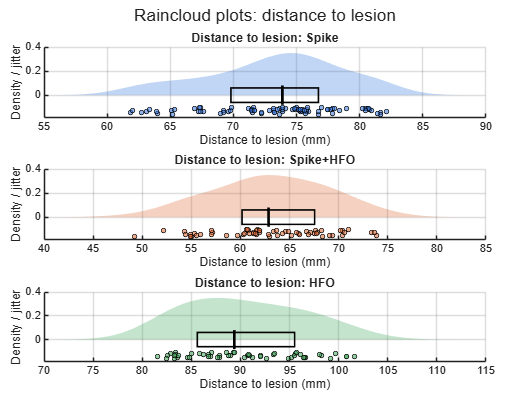

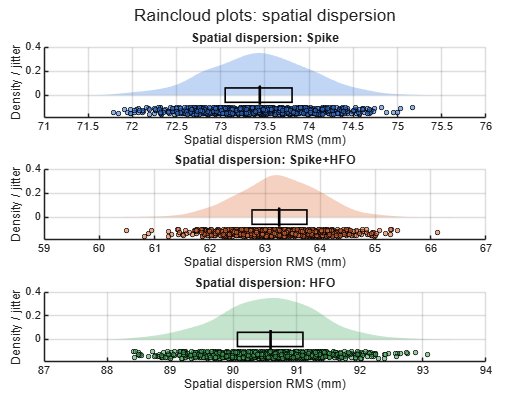

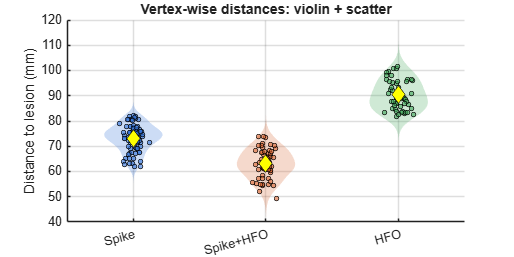

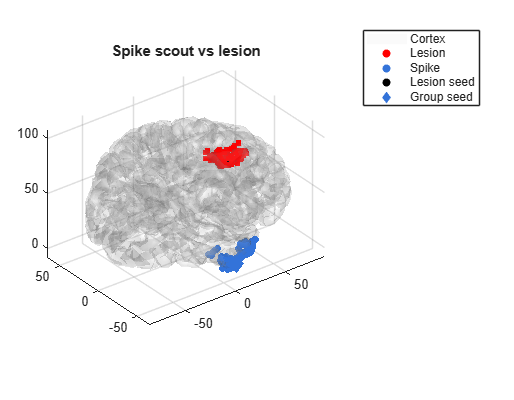

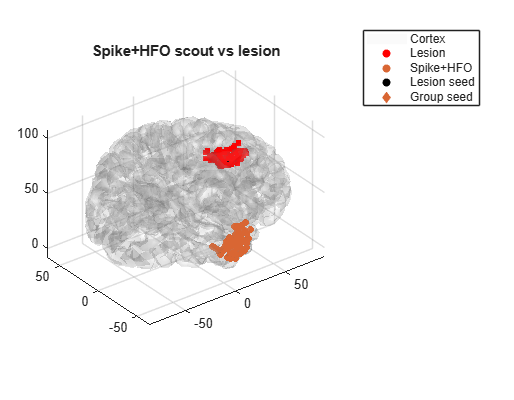

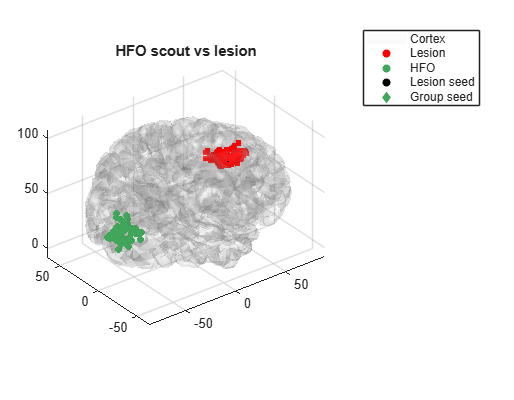


%% =========================
% 7) FIGURE 1: RAINCLOUD DISTANCE (SEPARATE SUBPLOTS)
%% =========================

fig1 = figure('Color','w','Position',[100 100 1100 850]);
tl = tiledlayout(nGroups,1,'TileSpacing','compact','Padding','compact');

for g = 1:nGroups
    ax = nexttile(tl);
    plot_single_raincloud(ax, vertex_distances{g}, group_colors(g,:), ...
        ['Distance to lesion: ' group_names{g}], ...
        'Distance to lesion (mm)');
end

title(tl, 'Raincloud plots: distance to lesion');

%% =========================
% 8) FIGURE 2: RAINCLOUD DISPERSION (SEPARATE SUBPLOTS)
%% =========================

fig2 = figure('Color','w','Position',[120 120 1100 850]);
tl2 = tiledlayout(nGroups,1,'TileSpacing','compact','Padding','compact');

for g = 1:nGroups
    ax = nexttile(tl2);
    plot_single_raincloud(ax, dispersion_boot{g}, group_colors(g,:), ...
        ['Spatial dispersion: ' group_names{g}], ...
        'Spatial dispersion RMS (mm)');
end

title(tl2, 'Raincloud plots: spatial dispersion');

%% =========================
% 9) FIGURE 3: VIOLIN + VERTEX-WISE DISTANCES
%% =========================

fig3 = figure('Color','w','Position',[140 140 1100 550]);
plot_grouped_violin_scatter(vertex_distances, group_names, group_colors, ...
    'Distance to lesion (mm)', ...
    'Vertex-wise distances: violin + scatter');

%% =========================
% 10) FIGURES 4-6: 3D RECONSTRUCTIONS
%% =========================

fig3D = gobjects(nGroups,1);

for g = 1:nGroups
    fig3D(g) = figure('Color','w','Position',[200+40*g 150+40*g 900 700]);

    if ~isempty(Faces)
        trisurf(Faces, VerticesMM(:,1), VerticesMM(:,2), VerticesMM(:,3), ...
            'FaceColor', [0.85 0.85 0.85], ...
            'EdgeColor', 'none', ...
            'FaceAlpha', 0.12);
        axis equal; hold on;
        lighting gouraud; camlight;
    else
        scatter3(VerticesMM(:,1), VerticesMM(:,2), VerticesMM(:,3), ...
            1, [0.8 0.8 0.8], 'filled');
        axis equal; hold on;
    end

    scatter3(lesion_coords_mm(:,1), lesion_coords_mm(:,2), lesion_coords_mm(:,3), ...
        20, 'r', 'filled');

    scatter3(group_coords_mm{g}(:,1), group_coords_mm{g}(:,2), group_coords_mm{g}(:,3), ...
        25, group_colors(g,:), 'filled');

    scatter3(lesion_seed_mm(1), lesion_seed_mm(2), lesion_seed_mm(3), ...
        80, 'k', 'filled');

    scatter3(group_seed_mm(g,1), group_seed_mm(g,2), group_seed_mm(g,3), ...
        100, group_colors(g,:), 'd', 'filled');

    legend({'Cortex', 'Lesion', group_names{g}, 'Lesion seed', 'Group seed'}, ...
        'Location', 'bestoutside');

    title([group_names{g} ' scout vs lesion']);
    view(3);
    rotate3d on;
end

%% =========================
% 11) SAVE HTML REPORT
%% =========================

output_folder = fileparts(spike_file);
html_folder   = fullfile(output_folder, 'html_export');
fig_folder    = fullfile(html_folder, 'figures');
html_file     = fullfile(html_folder, 'results_multi_group.html');

if ~exist(html_folder, 'dir')
    mkdir(html_folder);
end
if ~exist(fig_folder, 'dir')
    mkdir(fig_folder);
end

all_figs = [fig1; fig2; fig3; fig3D(:)];
all_captions = { ...
    'Raincloud plots: distance to lesion', ...
    'Raincloud plots: spatial dispersion', ...
    'Vertex-wise distances: violin + scatter', ...
    '3D reconstruction: Spike vs lesion', ...
    '3D reconstruction: Spike+HFO vs lesion', ...
    '3D reconstruction: HFO vs lesion'};

img_names = cell(numel(all_figs),1);

for i = 1:numel(all_figs)
    img_names{i} = sprintf('figure_%02d.png', i);
    img_path = fullfile(fig_folder, img_names{i});
    exportgraphics(all_figs(i), img_path, 'Resolution', 300);
end


fid = fopen(html_file, 'w');
if fid == -1
    error('No se pudo crear el archivo HTML.');
end

fprintf(fid, '<!DOCTYPE html>\n<html>\n<head>\n<meta charset="UTF-8">\n');
fprintf(fid, '<title>Results: Multi-group comparison vs lesion</title>\n');
fprintf(fid, '<style>\n');
fprintf(fid, 'body { font-family: Arial, sans-serif; margin: 40px; }\n');
fprintf(fid, 'table { border-collapse: collapse; width: 100%%; margin-bottom: 40px; }\n');
fprintf(fid, 'th, td { border: 1px solid #999; padding: 8px; text-align: center; }\n');
fprintf(fid, 'th { background-color: #f2f2f2; }\n');
fprintf(fid, 'img { max-width: 100%%; height: auto; border: 1px solid #ccc; margin-bottom: 20px; }\n');
fprintf(fid, '.figure-block { margin-bottom: 40px; }\n');
fprintf(fid, '</style>\n</head>\n<body>\n');

fprintf(fid, '<h1>Results: Multi-group comparison vs lesion</h1>\n');

fprintf(fid, '<h2>Numerical Results</h2>\n');
fprintf(fid, '<table>\n<tr>');
for c = 1:numel(ResultsTable.Properties.VariableNames)
    fprintf(fid, '<th>%s</th>', ResultsTable.Properties.VariableNames{c});
end
fprintf(fid, '</tr>\n');

for r = 1:height(ResultsTable)
    fprintf(fid, '<tr>');
    for c = 1:width(ResultsTable)
        val = ResultsTable{r,c};
        if iscell(val)
            val = val{1};
        end
        if ischar(val) || isstring(val)
            fprintf(fid, '<td>%s</td>', char(string(val)));
        elseif isnumeric(val)
            fprintf(fid, '<td>%.4f</td>', val);
        else
            fprintf(fid, '<td>%s</td>', '[unsupported]');
        end
    end
    fprintf(fid, '</tr>\n');
end
fprintf(fid, '</table>\n');

fprintf(fid, '<h2>Figures</h2>\n');
for i = 1:numel(img_names)
    fprintf(fid, '<div class="figure-block">\n');
    fprintf(fid, '<h3>%s</h3>\n', all_captions{i});
    fprintf(fid, '<img src="figures/%s" alt="%s">\n', img_names{i}, all_captions{i});
    fprintf(fid, '</div>\n');
end

fprintf(fid, '</body>\n</html>');
fclose(fid);

disp(['HTML report saved in: ' html_file]);

HTML report saved in: C:\Users\prego\Documents\datos_brainstorm\pacientes_rafa\AA\html_export\results_multi_group.html



%% =========================
% LOCAL FUNCTIONS
%% =========================

function scoutStruct = get_first_scout(S, varname)
    if ~isfield(S, 'Scouts') || isempty(S.Scouts)
        error('El archivo "%s" no contiene el campo Scouts o está vacío.', varname);
    end

    if numel(S.Scouts) > 1
        warning('El archivo "%s" contiene más de un scout. Se usará el primero.', varname);
    end

    scoutStruct = S.Scouts(1);
end

function seed_idx = get_scout_seed(scoutStruct)
    if isfield(scoutStruct, 'Seed') && ~isempty(scoutStruct.Seed)
        seed_idx = scoutStruct.Seed(1);
    elseif isfield(scoutStruct, 'Vertices') && ~isempty(scoutStruct.Vertices)
        seed_idx = scoutStruct.Vertices(1);
    else
        error('El scout no tiene ni Seed ni Vertices válidos.');
    end
end

function area_cm2 = compute_scout_area_cm2(Faces, VerticesRaw, scout_vertices, unit_scale)
    if isempty(Faces) || isempty(scout_vertices)
        area_cm2 = NaN;
        return;
    end

    nVertices = size(VerticesRaw,1);
    isScoutVertex = false(nVertices,1);
    isScoutVertex(scout_vertices) = true;

    faceMask = isScoutVertex(Faces(:,1)) & isScoutVertex(Faces(:,2)) & isScoutVertex(Faces(:,3));
    scoutFaces = Faces(faceMask, :);

    if isempty(scoutFaces)
        area_cm2 = 0;
        return;
    end

    total_area_raw = 0;

    for i = 1:size(scoutFaces,1)
        v1 = VerticesRaw(scoutFaces(i,1), :);
        v2 = VerticesRaw(scoutFaces(i,2), :);
        v3 = VerticesRaw(scoutFaces(i,3), :);

        tri_area = 0.5 * norm(cross(v2 - v1, v3 - v1));
        total_area_raw = total_area_raw + tri_area;
    end

    % raw units -> mm² -> cm²
    area_cm2 = total_area_raw * (unit_scale^2) / 100;
end

function bootVals = bootstrap_rms_distribution(d, nBoot)
    d = d(:);
    n = numel(d);
    bootVals = zeros(nBoot,1);

    for b = 1:nBoot
        idx = randi(n, n, 1);
        sample = d(idx);
        bootVals(b) = sqrt(mean(sample.^2));
    end
end

function plot_single_raincloud(ax, x, colorRGB, ttl, xlab)
    axes(ax); %#ok<LAXES>
    cla(ax); hold(ax, 'on');

    x = x(:);
    x = x(~isnan(x));

    if isempty(x)
        title(ax, ttl);
        xlabel(ax, xlab);
        ylabel(ax, 'Density / jitter');
        grid(ax, 'on');
        return;
    end

    [f, xi] = local_density(x);
    f = f(:);
    xi = xi(:);

    if max(f) > 0
        f = f ./ max(f);
    end
    f = 0.35 * f;

    % Half violin / cloud above y=0
    xpatch = [xi; flipud(xi)];
    ypatch = [f; zeros(size(f))];
    patch('XData', xpatch, ...
          'YData', ypatch, ...
          'FaceColor', colorRGB, ...
          'FaceAlpha', 0.30, ...
          'EdgeColor', 'none', ...
          'Parent', ax);

    % Box summary around baseline
    q1  = quantile(x, 0.25);
    q3  = quantile(x, 0.75);
    med = median(x);

    rectangle(ax, 'Position', [q1, -0.06, q3-q1, 0.12], ...
        'EdgeColor', 'k', 'LineWidth', 1.2);
    plot(ax, [med med], [-0.08 0.08], 'k-', 'LineWidth', 2);

    % Jittered points below
    yj = -0.10 - 0.06*rand(size(x));
    scatter(ax, x, yj, 12, ...
        'MarkerFaceColor', colorRGB, ...
        'MarkerEdgeColor', 'k', ...
        'MarkerFaceAlpha', 0.55);

    title(ax, ttl);
    xlabel(ax, xlab);
    ylabel(ax, 'Density / jitter');
    grid(ax, 'on');
    box(ax, 'off');
    ylim(ax, [min(yj)-0.03, max(f)+0.05]);
    hold(ax, 'off');
end

function plot_grouped_violin_scatter(dataCell, group_names, group_colors, ylab, ttl)
    hold on;

    nGroups = numel(dataCell);

    for g = 1:nGroups
        y = dataCell{g};
        y = y(~isnan(y));
        if isempty(y)
            continue;
        end

        [f, xi] = local_density(y);
        f = f(:);
        xi = xi(:);

        if max(f) > 0
            f = f ./ max(f);
        end
        f = 0.22 * f;

        xpatch = [g - f; flipud(g + f)];
        ypatch = [xi; flipud(xi)];

        patch('XData', xpatch, ...
              'YData', ypatch, ...
              'FaceColor', group_colors(g,:), ...
              'FaceAlpha', 0.25, ...
              'EdgeColor', 'none');

        xj = g + 0.05*randn(size(y));
        scatter(xj, y, 12, ...
            'MarkerFaceColor', group_colors(g,:), ...
            'MarkerEdgeColor', 'k', ...
            'MarkerFaceAlpha', 0.6);

        plot(g, mean(y), 'kd', 'MarkerFaceColor', 'y', 'MarkerSize', 9);
    end

    set(gca, 'XTick', 1:nGroups, 'XTickLabel', group_names, 'XTickLabelRotation', 15);
    ylabel(ylab);
    title(ttl);
    grid on;
    box off;
    hold off;
end

function [f, xi] = local_density(y)
    y = y(:);

    if isempty(y)
        xi = linspace(0,1,50)';
        f = zeros(size(xi));
        return;
    end

    if numel(unique(y)) == 1
        xi = linspace(y(1)-1e-6, y(1)+1e-6, 50)';
        f  = ones(size(xi));
        return;
    end

    try
        [f, xi] = ksdensity(y);
        f = f(:);
        xi = xi(:);
    catch
        [counts, edges] = histcounts(y, 30, 'Normalization', 'pdf');
        xi = ((edges(1:end-1) + edges(2:end))/2)';
        f  = counts(:);
    end
end
